# Simulating Flows

In this recitation, we will work towards a better understanding about how to simulating the movement of particles on a discrete flow field. In particular, this will be helpful for the section project where you will be asked to use simulation of particle movement on oceanic data presented in the form of discrete flow fields.

**Disclaimer 1: **This is by no means, a comprehensive study of computational fluid dynamics. To the interested reader please see: Stam, Jos. "**Stable fluids."** in the* Proceedings of the 26th Annual Conference on Computer graphics and Interactive Techniques 1999*. Another great source for fluid simulations can be found in [https://www.karlsims.com/flow.html](https://www.karlsims.com/flow.html)

**Disclaimer 2:** In this recitation, we will work only on 2-dimensional spaces. However, the techinques and procedues can be extended to other spaces.

**Disclaimer 3: **We will initially focus on the movement of a single particle. For simulating multiple non-interacting particles the process scales similarly. We do not consider interacting particles.

## What is a flow?

A flow refers to displacement in time, that is if $x(t)$denotes the location of a particle at time $t$. Then, we define the flow vector as


$$\frac{d x(t)}{dt}= V(x(t),t).$$


or similarly, their explicit Euler discretization as,  for a small $\varepsilon >0$, then


$$x(t+\varepsilon) = x(t) + \varepsilon V(x(t),t).$$


Informally, if we know the position of a particle at time $t$, then, after some arbitrarily small time $\varepsilon$, that is, at time $t+\varepsilon$, we can compute the new position $x\left(t+\varepsilon \right)$ as $x\left(t+\varepsilon \right)=x\left(t\right)+\varepsilon V\left(x\left(t\right),t\right)$, assuming we know the flow information coded in the function $V\left(x\left(t\right),t\right)$.

### **The ingreadients for simulating a flow:**

As noted by the description above, in order to simulate the movement of the particle we need a couple of items:

- A space $\mathcal{X}$ where we want out simulation to be run on. For example for a 2-dimensional space, we can consider a box with unitary lenght, i.e., $\mathcal{X} = [0,1]\times [0,1]$.

- An initial position $x(0) \in \mathcal{X}$. Of course we want our initial position to be inside the space we want to simulate the movement.

- A simulation time $T$. This is the maximum time we would like to run our simulation.

- A time step $T\ge \varepsilon >0$. The unit $\varepsilon$ is going to serve as a discretization of time, and is going to the the smallest unit of time we are going to consider in our simulation. In practice, this means our simulation should output a sequence of positions for times $\left\lbrace 0,\varepsilon ,2\varepsilon ,3\varepsilon ,4\varepsilon ,\cdots ,T\right\rbrace$.

- The number $\varepsilon$ also defines the number of iterations we are going to have in our simulation. For example, if $T=10$, and $\varepsilon =2$, then we will run a total of $N=5$ iterations. One can start the oposite direction, by defining the number of iterations first and then compute the corresponding time step. For example, if I want to run $N=300$ iterations, I will have to set $\varepsilon =\frac{T}{N}=\frac{10}{300}=0\ldotp 033$.

- A flow function $V(x(t),t): \mathcal{X}\times [0,T]\to \mathbb{R}^2$. This function has two input arguments, namely, a position $x\left(t\right)$ and a time $t$, and outputs a vector in $\mathbb{R}^2
$ which indicates the velocity that a particle at location $x\left(t\right)$ would have in the $x$ and $y\;$axis respectively. Note that we have explicitely allowed the flow function to depend on time. That is, flows might change dependeing not only on the location but of the time index.

- In general, we might not have access to a generic function of the form $V(x(t),t): \mathcal{X}\times [0,T]\to \mathbb{R}^2$, specially if our flow comes from data that has been obtained at some particular set of locations. In this case, we might consider a set $\mathcal{G} =\{x_1,x_2,\cdots, x_m \}$where $x_i \in \mathcal{X}$ for $i\in \left\lbrace 1,2,\cdots ,m\right\rbrace$. These points represents the locations where flow information is available. For simulation purposes in this case, if at some point in time $t\in \left\lbrack 0,T\right\rbrack$, the particle is at a location $x\left(t\right)$, instead of using the flow $V\left(x\left(t\right),t\right)$ which might not be available, we will use the surrogate flow $V\left(x_j ,t\right)$ where $x_j = \arg\min_{z \in \mathcal{G}} d(z,x(t))$where $d\left(\cdot ,\cdot \right)$ is some distance function, for example $d\left(x,y\right)=\left\|x-y{\left\|\right.}^2 \ldotp \right.$ This indicates that we will use the flow information at a point $x_j$ in the set of available locations, that is closest to $x\left(t\right)$ in some predined sense.

Next, we will create a sequence of increasingly complex sample codes that will helps us better understand the simulation process.

## Example 1: A particle on a constant flow field.

In this example, we are going to simate the movement of a single particle on a box with unitary lengt. Moreover, we are going to assume the velicty information or the flow data is constant on this box. You will be able to set the maximum time of the simulation, the number of steps, the initial position of the particle. and the velocity of the flow in the x and y axis.

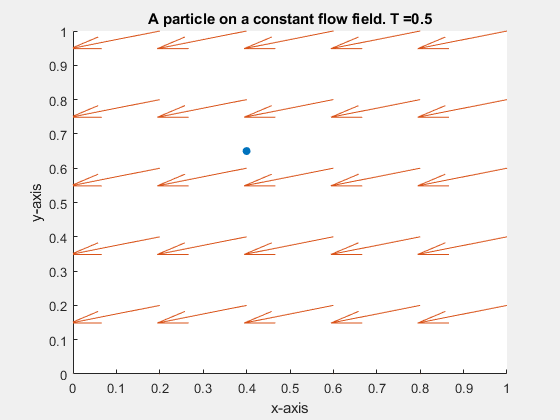

clear all                                % Cleaning the memory 
%Setting the parameters
T = 2;                % We set the maximum simulation time to 5
N = 100;                % We want our simulation to run for 100 iterations.
epsilon = T/N;          % The time step of our simulation
t=0;

%Bounding the space limits, upper and lower limits for the x and y axis
x_max = 1;
x_min = 0;
y_max = 1;
y_min = 0;

%Setting the initial location of the particle
x_0(1) = 0.6;
x_0(2) = 0.7;

%Setting the velocity
v(1) = -0.4;
v(2) = -0.1;

 

%Create a Mesh for showing the flow data
[g_x,g_y] = meshgrid(0:0.2:1,0:0.2:1);
w_x = ones(size(g_x,1))*v(1);
w_y = ones(size(g_x,1))*v(2);

%Create and position a figure to plot
f = figure;
f.Position = f.Position.*[1 1 1 1];
clf

%Make an initial plot
x = x_0;
h= scatter(x(1),x(2),'filled','o');
xlabel('x-axis') ; ylabel('y-axis')
axis([0 1 0 1])
title('A particle on a constant flow field2. T =0')
hold on
%Plot the flow information
quiver(g_x,g_y,w_x,w_y)
hold off


%Do N iterations
for i=1:N+1
    
    xp(:,i) = x;                                % Storing all the positions of the particle
    
    x = x + epsilon*v;                          % Compute the next position value
    t = t+epsilon;                              % Compute the next time
    
    % Safety stop if particle goes out of bounds.
    if sum(x >1) || sum(x<0)
        break               % This will terminate the for loop
    end

    
    %Drawing point in new position and changing the time information
    set(h, 'XData', x(1), 'YData', x(2))
    title(strcat('A particle on a constant flow field. T =',num2str(t)))
    drawnow
        
end
hold on
scatter(xp(1,1),xp(2,1),'xk');
plot(xp(1,:),xp(2,:),'-')
hold off

## Example 2: A particle on a oscillating field

As a second example, we will assume that the velocities of the flow in the x and y axis follow an oscinalting behaviour, with certain frequency.

clear all

f=2;    % Set the frecuency
T = 2;                          % Set the maximum simulation time
N = 100;                        % Set the number of iterations

%Setting the initial location of the particle
x_0(1) = 0.6;
x_0(2) = 0.5;

 

epsilon=T/N;                    % Compute the time step-size

t = [0:epsilon:T];              % Create the vector of times
v_x = sin(2*pi*f*t);            % Compute the velocity values at every time instant
v_y = cos(2*pi*f*t);            % Compute the velocity values at every time instant

%Plot the velocities
f = figure;
f.Position = f.Position.*[1 1 1 1];
clf


%Bounding the space limits, upper and lower limits for the x and y axis
x_max = 1;
x_min = 0;
y_max = 1;
y_min = 0;


subplot(121)
h1= plot(t,v_x);
xlabel('time') ; ylabel('x-axis velocity')
title('Velocity in the x-axis')
subplot(122)
h2= plot(t,v_y);
xlabel('time') ; ylabel('y-axis velocity')
title('Velocity in the y-axis')
%Create a Mesh for showing the flow data
[g_x,g_y] = meshgrid(0:0.2:1,0:0.2:1);
w_x = ones(size(g_x,1))*v_x(1);
w_y = ones(size(g_x,1))*v_y(1);
v = [v_x(1),v_y(1)];

%Create and position a figure to plot
f = figure;
f.Position = f.Position.*[1 1 1 1];
clf

%Make an initial plot
x = x_0;
h= scatter(x(1),x(2),'filled','o');
xlabel('x-axis') ; ylabel('y-axis')
axis([0 1 0 1])
title('A particle on a constant flow field2. T =0')
hold on
%Plot the flow information
hq = quiver(g_x,g_y,w_x,w_y);

%Do N iterations
for i=1:N+1
    
    xp(:,i) = x;                                % Storing all the positions of the particle
    
    x = x + epsilon*v;                          % Compute the next position value
    
    %Safety stop if particle goes out of bounds.
    if sum(x >1) || sum(x<0)
        break               % This will terminate the for loop
    end
    
    %Drawing point in new position and changing the time information
    set(h, 'XData', x(1), 'YData', x(2))
    title(strcat('A particle on a constant flow field. T =',num2str(t(i))))
    
    %Update the velocity information for the new time step
    w_x = ones(size(g_x,1))*v_x(i);
    w_y = ones(size(g_x,1))*v_y(i);
    v = [v_x(i),v_y(i)];
    
    %Plot the updated flow information
    set(hq, 'UData',w_x, 'VData', w_y)
    drawnow

end
hold on
scatter(xp(1,1),xp(2,1),'xk');
plot(xp(1,:),xp(2,:),'-')
hold off

## Example 3:  A particle on a random velocity field

In this simulation, we will assume that the velocity changes as a realizaition of a uniform random variable on the range [-1,1]. However, contrary to Example 2, the changes do not happen at every iteration. But only every 0.3 units of time. So we need to take chare of that.

clear all

T = 2;                          % Set the maximum simulation time
N = 100;                        % Set the number of iterations
%Setting the initial location of the particle
x_0(1) = 0.5;
x_0(2) = 0.5;

 

epsilon=T/N;                    % Compute the time step-size

t = [0:epsilon:T];              % Create the vector of times

%Bounding the space limits, upper and lower limits for the x and y axis
x_max = 1;
x_min = 0;
y_max = 1;
y_min = 0;

%Set a random flow for each region
v_x = 1*rand(1)-0.5;                % Generates a grid of 2x2 of random velocities for the x-axis
v_y = 1*rand(1)-0.5;                % Generates a grid of 2x2 of random velocities for the x-axis

%Create a Mesh for showing the flow data
[g_x,g_y] = meshgrid(0:0.2:1,0:0.2:1);
w_x = ones(size(g_x,1))*v_x(1);
w_y = ones(size(g_x,1))*v_y(1);
v = rand(2,1)-0.5;

%Create and position a figure to plot
f = figure;
f.Position = f.Position.*[1 1 1 1];
clf

%Make an initial plot
x = x_0';
h= scatter(x(1),x(2),'filled','o');
xlabel('x-axis') ; ylabel('y-axis')
axis([0 1 0 1])
title('A particle on a constant flow field2. T =0')
hold on
%Plot the flow information
hq = quiver(g_x,g_y,w_x,w_y);

%Do N iterations
for i=1:N+1
    
    xp(:,i) = x;                                % Storing all the positions of the particle
   
    x = x + epsilon*v;                          % Compute the next position value
    
    %Safety stop if particle goes out of bounds.
    if sum(x >1) || sum(x<0)
        break               % This will terminate the for loop
    end
    
    %Drawing point in new position and changing the time information
    set(h, 'XData', x(1), 'YData', x(2))
    title(strcat('A particle on a constant flow field. T =',num2str(t(i))))
    
    if mod(i*epsilon,0.5)==0
        v_x = 2*rand(1)-1;      % Compute the velocity values at every time instant
        v_y = 2*rand(1)-1;      % Compute the velocity values at every time instant
        
        %Update the velocity information for the new time step
        w_x = ones(size(g_x,1))*v_x;
        w_y = ones(size(g_x,1))*v_y;
        v = 0.5*[v_x;v_y];
    end
    
    %Plot the updated flow information
    set(hq, 'UData',w_x, 'VData', w_y)
    drawnow
end
hold on
scatter(xp(1,1),xp(2,1),'xk');
plot(xp(1,:),xp(2,:),'-')
hold off

## Exercise 4: Multiple particles in a random across time velocity field

In this exercose, we repeat the setup of Exercise 3, with the main difference of simulating several particles at once.

clear all

T = 2;                          % Set the maximum simulation time
N = 100;                        % Set the number of iterations
n = 2;

 
epsilon=T/N;                    % Compute the time step-size

t = [0:epsilon:T];              % Create the vector of times

%Bounding the space limits, upper and lower limits for the x and y axis
x_max = 1;
x_min = 0;
y_max = 1;
y_min = 0;

%We assign a random initial position to each particle
x_0_x = 0.5*rand(n,1)+0.25;
x_0_y = 0.5*rand(n,1)+0.25;

%Set a random flow for each region
v_x = 1*rand(1)-0.5;                % Generates a grid of 2x2 of random velocities for the x-axis
v_y = 1*rand(1)-0.5;                % Generates a grid of 2x2 of random velocities for the x-axis


%Create a Mesh for showing the flow data
[g_x,g_y] = meshgrid(0:0.2:1,0:0.2:1);
w_x = ones(size(g_x,1))*v_x(1);
w_y = ones(size(g_x,1))*v_y(1);
v = rand(2,1)-0.5;

%Create and position a figure to plot
f = figure;
f.Position = f.Position.*[1 1 1 1];
clf

%Make an initial plot
x_x = x_0_x;
x_y = x_0_y;
h= scatter(x_x,x_y,'filled','o');
xlabel('x-axis') ; ylabel('y-axis')
axis([0 1 0 1])
title('A particle on a constant flow field2. T =0')
hold on
%Plot the flow information
hq = quiver(g_x,g_y,w_y,w_x);

%Do N iterations
for i=1:N+1
    
    xp_x(:,i) = x_x;
    xp_y(:,i) = x_y;
    
    x_x = x_x + epsilon*v(1);                          % Compute the next position value
    x_y = x_y + epsilon*v(2);                          % Compute the next position value
    
    %Drawing point in new position and changing the time information
    set(h, 'XData', x_x, 'YData', x_y)
    title(strcat('A particle on a constant flow field. T =',num2str(t(i))))
    
    if mod(i*epsilon,0.5)==0
        v_x = 2*rand(1)-1;      % Compute the velocity values at every time instant
        v_y = 2*rand(1)-1;      % Compute the velocity values at every time instant
        
        %Update the velocity information for the new time step
        w_x = ones(size(g_x,1))*v_x;
        w_y = ones(size(g_x,1))*v_y;
        v = 0.1*[v_x;v_y];
    end
    
    %Plot the updated flow information
    set(hq, 'UData',w_x, 'VData', w_y)
    drawnow
end

%Plot initial condition and trajectories
hold on
scatter(xp_x(:,1),xp_y(:,1),'xk');
plot(xp_x',xp_y','-')
hold off

## Exercise 5: One particle over four regions with different flows but constant over time

Up to now, all previous exercises work under the case that the velocity field is constant acroos the space $\mathcal{X}$. We have allowed changes across time, but the flow was the same at every point in the space. In the next couple of exercises, we are going to study what happens if we allow for the flow to be different at different regions in the space. You will see this case explicitely in the project, where you will be given flow information for a number of locations, and such flows change over the space.

Initially, consider that we partition our unitary square into four regions as shown below.

clear all

%Plot a grid 

f = figure;
f.Position = f.Position.*[1 1 1 1];
clf
xlabel('x-axis') ; ylabel('y-axis')
axis([0 1 0 1])
hold on
plot([0.5 0.5], [0 1], 'r', 'LineWidth', 2)
plot([0 0], [0 1], 'r', 'LineWidth', 2)
plot([1 1], [0 1], 'r', 'LineWidth', 2)
plot([0 1], [0.5 0.5], 'r', 'LineWidth', 2)
plot([0 1], [0 0], 'r', 'LineWidth', 2)
plot([0 1], [1 1], 'r', 'LineWidth', 2)
text(0.25,0.25,'Region 1')
text(0.75,0.25,'Region 2')
text(0.25,0.75,'Region 3')
text(0.75,0.75,'Region 4')
hold off

 

Moreover, we will assume the flow in each of the regious is different. For example

%Recreate the grid from above 

f = figure;
f.Position = f.Position.*[1 1 1 1];
clf
xlabel('x-axis') ; ylabel('y-axis')
axis([0 1 0 1])
hold on
plot([0.5 0.5], [0 1], 'r', 'LineWidth', 2)
plot([0 0], [0 1], 'r', 'LineWidth', 2)
plot([1 1], [0 1], 'r', 'LineWidth', 2)
plot([0 1], [0.5 0.5], 'r', 'LineWidth', 2)
plot([0 1], [0 0], 'r', 'LineWidth', 2)
plot([0 1], [1 1], 'r', 'LineWidth', 2)
text(0.25,0.25,'Region 1')
text(0.75,0.25,'Region 2')
text(0.25,0.75,'Region 3')
text(0.75,0.75,'Region 4')


%Set a random flow for each region
v_x = 1*rand(2,2)-0.5;                % Generates a grid of 2x2 of random velocities for the x-axis
v_y = 1*rand(2,2)-0.5;                % Generates a grid of 2x2 of random velocities for the x-axis

[g_x,g_y] = meshgrid(0.25:0.5:1,0.25:0.5:1);
w_x = v_x;
w_y = v_y;
hq = quiver(g_x,g_y,w_y,w_x);
hold off

 

Now, lets simulate the movement of a particle in a flow that is partitioned in those four regions described above. The main trick now is that we need to see in what region the particle is before computing the next position.

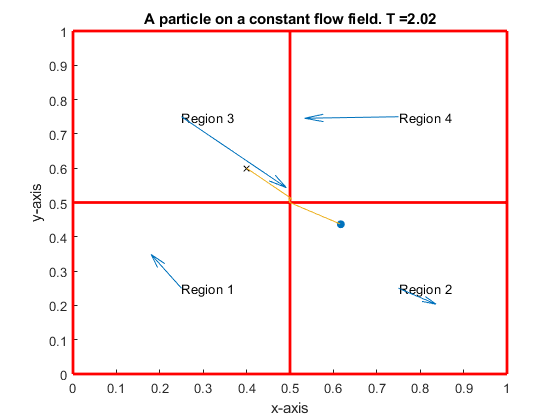

%Setting the parameters
T = 2;                % We set the maximum simulation time to 5
N = 100;                % We want our simulation to run for 100 iterations.

% Setting the initial location of the particle
x_0(1) = 0.4;
x_0(2) = 0.6;
 

epsilon = T/N;          % The time step of our simulation
t=0;

%Bounding the space limits, upper and lower limits for the x and y axis
x_max = 1;
x_min = 0;
y_max = 1;
y_min = 0;

% Set a random flow for each region
v_x = 0.5*rand(2,2)-0.25;                % Generates a grid of 2x2 of random velocities for the x-axis
v_y = 0.5*rand(2,2)-0.25;                % Generates a grid of 2x2 of random velocities for the x-axis

[g_x,g_y] = meshgrid(0.25:0.5:1,0.25:0.5:1);
w_x = v_x;
w_y = v_y;

%Create and position a figure to plot
f = figure;
f.Position = f.Position.*[1 1 1 1];
clf

%Make an initial plot
x = x_0;
h= scatter(x(1),x(2),'filled','o');
xlabel('x-axis') ; ylabel('y-axis')
axis([0 1 0 1])
title('A particle on a constant flow field2. T =0')
hold on

%Plot the grid
plot([0.5 0.5], [0 1], 'r', 'LineWidth', 2)
plot([0 0], [0 1], 'r', 'LineWidth', 2)
plot([1 1], [0 1], 'r', 'LineWidth', 2)
plot([0 1], [0.5 0.5], 'r', 'LineWidth', 2)
plot([0 1], [0 0], 'r', 'LineWidth', 2)
plot([0 1], [1 1], 'r', 'LineWidth', 2)
text(0.25,0.25,'Region 1')
text(0.75,0.25,'Region 2')
text(0.25,0.75,'Region 3')
text(0.75,0.75,'Region 4')

%Plot the flow information
quiver(g_y,g_x,w_x,w_y)

%Do N iterations
for i=1:N+1
    
    xp(:,i) = x;                                % Storing all the positions of the particle
    
    %Now we determine the location of the particle to set up the speed
    ind_g = round(2*x+0.5);
    ind_g(ind_g>2) =2;              % Just checking that we dont go out of bounds
    ind_g(ind_g<1) =1;              % Just checking that we dont go out of bounds
    
    v(1) = v_x(ind_g(1),ind_g(2));  % Set the new speed according to the region 
    v(2) = v_y(ind_g(1),ind_g(2));  % Set the new speed according to the region
    
    x = x + epsilon*v;                          % Compute the next position value
    
    %Safety stop if particle goes out of bounds.
    if sum(x >1) || sum(x<0)
        break               % This will terminate the for loop
    end
    
    t = t+epsilon;                              % Compute the next time
    
    %Drawing point in new position and changing the time information
    set(h, 'XData', x(1), 'YData', x(2))
    title(strcat('A particle on a constant flow field. T =',num2str(t)))
    drawnow
        
end

%Plot initial condition and trajectories
hold on
scatter(xp(1,1),xp(2,1),'xk');
plot(xp(1,:),xp(2,:),'-')
hold off

## Exercise 6: One particle on a generic $m\times m$ grid with constant flows over time

In Exercise 5, we have simulated the movement of one particle on a 2 by 2 grid. In this exercise, we will do so for generic grid fo m by m regions.

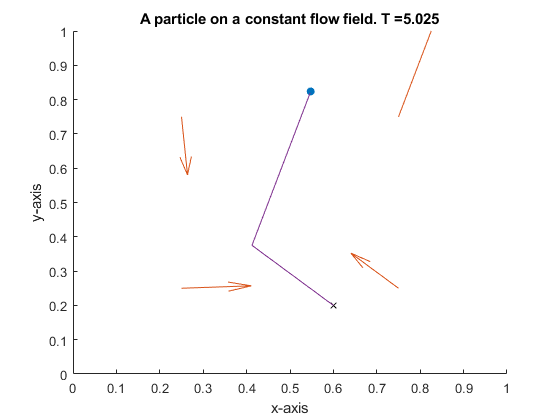

%% Setting the parameters
T = 5;                % We set the maximum simulation time to 5
N = 200;                % We want our simulation to run for 100 iterations.
m =2;
x_0(1) = 0.6;
x_0(2) = 0.2;
 

epsilon = T/N;          % The time step of our simulation
t=0;

%% Bounding the space limits, upper and lower limits for the x and y axis
x_max = 1;
x_min = 0;
y_max = 1;
y_min = 0;

% Setting the initial location of the particle

%% Set a random flow for each region
v_x = 0.4*rand(m)-0.2;                % Generates a grid of 2x2 of random velocities for the x-axis
v_y = 0.4*rand(m)-0.2;                % Generates a grid of 2x2 of random velocities for the x-axis

[g_x,g_y] = meshgrid(1/(2*m):1/(m):1-1/(2*m),1/(2*m):1/(m):1-1/(2*m));
w_x = v_x;
w_y = v_y;

% Create and position a figure to plot
f = figure;
f.Position = f.Position.*[1 1 1 1];
clf

% Make an initial plot
x = x_0;
h= scatter(x(1),x(2),'filled','o');
xlabel('x-axis') ; ylabel('y-axis')
axis([0 1 0 1])
title('A particle on a constant flow field2. T =0')
hold on

% Plot the flow information
quiver(g_y,g_x,w_x,w_y)
hold off

% Do N iterations
for i=1:N+1
    
    xp(:,i) = x;                                % Storing all the positions of the particle
    
    % Now we determine the location of the particle to set up the speed
    ind_g = ceil(m*x+1/(2*m));
    ind_g(ind_g>m) =m;              % Just checking that we dont go out of bounds
    ind_g(ind_g<1) =1;              % Just checking that we dont go out of bounds
    
    v(1) = v_x(ind_g(1),ind_g(2));  % Set the new speed according to the region 
    v(2) = v_y(ind_g(1),ind_g(2));  % Set the new speed according to the region
    
    x = x + epsilon*v;                          % Compute the next position value
    
    % Safety stop if particle goes out of bounds.
    if sum(x >1) || sum(x<0)
        break               % This will terminate the for loop
    end
    
    t = t+epsilon;                              % Compute the next time
    
    % Drawing point in new position and changing the time information
    set(h, 'XData', x(1), 'YData', x(2))
    drawnow
    title(strcat('A particle on a constant flow field. T =',num2str(t)))
    
        
end

% Plot initial condition and trajectories
hold on
scatter(xp(1,1),xp(2,1),'xk');
plot(xp(1,:),xp(2,:),'-')
hold off

## Exercise 7: Multiple particles on a generic $m\times m$ grid with constant flows over time

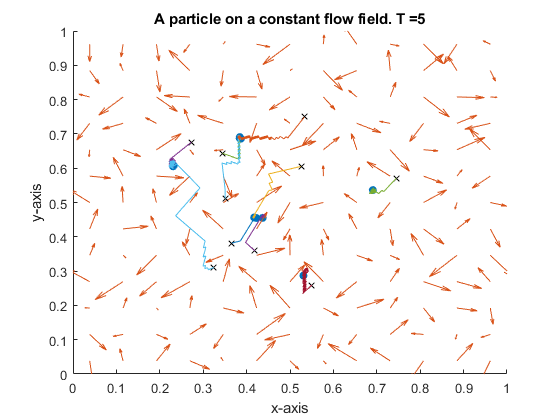

clear all

T = 5;                          % Set the maximum simulation time
N = 100;                        % Set the number of iterations
n = 10;
m =13;
 

epsilon=T/N;                    % Compute the time step-size

t = [0:epsilon:T];              % Create the vector of times

%Bounding the space limits, upper and lower limits for the x and y axis
x_max = 1;
x_min = 0;
y_max = 1;
y_min = 0;

%We assign a random initial position to each particle
x_0_x = 0.5*rand(n,1)+0.25;
x_0_y = 0.5*rand(n,1)+0.25;

%% Set a random flow for each region
v_x = 0.4*rand(m)-0.2;                % Generates a grid of 2x2 of random velocities for the x-axis
v_y = 0.4*rand(m)-0.2;                % Generates a grid of 2x2 of random velocities for the x-axis

[g_x,g_y] = meshgrid(1/(2*m):1/(m):1-1/(2*m),1/(2*m):1/(m):1-1/(2*m));
w_x = v_x;
w_y = v_y;

%Create and position a figure to plot
f = figure;
f.Position = f.Position.*[1 1 1 1];
clf

%Make an initial plot
x_x = x_0_x;
x_y = x_0_y;
h= scatter(x_x,x_y,'filled','o');
xlabel('x-axis') ; ylabel('y-axis')
axis([0 1 0 1])
title('A particle on a constant flow field2. T =0')
hold on
%Plot the flow information
hq = quiver(g_x,g_y,w_x,w_y);

%Do N iterations
for i=1:N+1
    
    xp_x(:,i) = x_x;
    xp_y(:,i) = x_y;
    
    % Now we determine the location of the particle to set up the speed
    % We will check this for the two coordinates independently
    ind_g_x = ceil(m*x_x+1/(2*m));
    ind_g_x(ind_g_x>m) =m;              % Just checking that we dont go out of bounds
    ind_g_x(ind_g_x<1) =1;              % Just checking that we dont go out of bounds
    
    ind_g_y = ceil(m*x_y+1/(2*m));
    ind_g_y(ind_g_y>m) =m;              % Just checking that we dont go out of bounds
    ind_g_y(ind_g_y<1) =1;              % Just checking that we dont go out of bounds
    
    v(:,1) = v_x(sub2ind([m,m],ind_g_x',ind_g_y'))';  % Set the new speed according to the region 
    v(:,2) = v_y(sub2ind([m,m],ind_g_x',ind_g_y'))';  % Set the new speed according to the region
    
    x_x = x_x + epsilon*v(:,1);                          % Compute the next position value
    x_y = x_y + epsilon*v(:,2);                          % Compute the next position value
    
    %Drawing point in new position and changing the time information
    set(h, 'XData', x_x, 'YData', x_y)
    title(strcat('A particle on a constant flow field. T =',num2str(t(i))))
    drawnow
    
end

%Plot initial condition and trajectories
hold on
scatter(xp_x(:,1),xp_y(:,1),'xk');
plot(xp_x',xp_y','-')
hold off

## Exercise 8: Multiple particles on a generic $m\times m$ grid on a flow that changes with time

This case is very similar as Exercise 7, with the main difference that we will allowe changes in the flows from time to time. Especifically we change the flows every 0.5 units of time

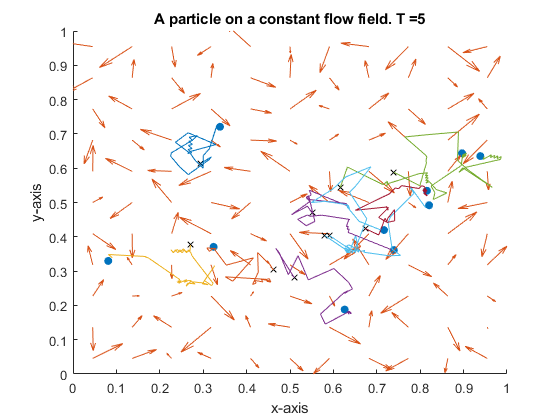

clear all

T = 5;                          % Set the maximum simulation time
N = 100;                        % Set the number of iterations
n = 10;
m =11;

 

epsilon=T/N;                    % Compute the time step-size

t = [0:epsilon:T];              % Create the vector of times

%Bounding the space limits, upper and lower limits for the x and y axis
x_max = 1;
x_min = 0;
y_max = 1;
y_min = 0;

%We assign a random initial position to each particle
x_0_x = 0.5*rand(n,1)+0.25;
x_0_y = 0.5*rand(n,1)+0.25;

%% Set a random flow for each region
v_x = 0.4*rand(m)-0.2;                % Generates a grid of 2x2 of random velocities for the x-axis
v_y = 0.4*rand(m)-0.2;                % Generates a grid of 2x2 of random velocities for the x-axis

[g_x,g_y] = meshgrid(1/(2*m):1/(m):1-1/(2*m),1/(2*m):1/(m):1-1/(2*m));
w_x = v_x;
w_y = v_y;

%Create and position a figure to plot
f = figure;
f.Position = f.Position.*[1 1 1 1];
clf

%Make an initial plot
x_x = x_0_x;
x_y = x_0_y;
h= scatter(x_x,x_y,'filled','o');
xlabel('x-axis') ; ylabel('y-axis')
axis([0 1 0 1])
title('A particle on a constant flow field2. T =0')
hold on
%Plot the flow information
hq = quiver(g_x,g_y,w_x,w_y);

%Do N iterations
for i=1:N+1
    
    xp_x(:,i) = x_x;
    xp_y(:,i) = x_y;
    
    % Now we determine the location of the particle to set up the speed
    % We will check this for the two coordinates independently
    ind_g_x = ceil(m*x_x+1/(2*m));
    ind_g_x(ind_g_x>m) =m;              % Just checking that we dont go out of bounds
    ind_g_x(ind_g_x<1) =1;              % Just checking that we dont go out of bounds
    
    ind_g_y = ceil(m*x_y+1/(2*m));
    ind_g_y(ind_g_y>m) =m;              % Just checking that we dont go out of bounds
    ind_g_y(ind_g_y<1) =1;              % Just checking that we dont go out of bounds
    
    v(:,1) = v_x(sub2ind([m,m],ind_g_x',ind_g_y'))';  % Set the new speed according to the region 
    v(:,2) = v_y(sub2ind([m,m],ind_g_x',ind_g_y'))';  % Set the new speed according to the region
    
    x_x = x_x + epsilon*v(:,1);                          % Compute the next position value
    x_y = x_y + epsilon*v(:,2);                          % Compute the next position value
    
    if mod(i*epsilon,0.5)==0
        v_x = 0.4*rand(m)-0.2;                % Generates a grid of 2x2 of random velocities for the x-axis
        v_y = 0.4*rand(m)-0.2;                % Generates a grid of 2x2 of random velocities for the x-axis
        
        %Plot the updated flow information
        set(hq, 'UData',v_x, 'VData', v_y)
    end
    
    %Drawing point in new position and changing the time information
    set(h, 'XData', x_x, 'YData', x_y)
    title(strcat('A particle on a constant flow field. T =',num2str(t(i))))
    
    drawnow
end

%Plot initial condition and trajectories
hold on
scatter(xp_x(:,1),xp_y(:,1),'xk');
plot(xp_x',xp_y','-')
hold off

## Exercise 9: Working with realistic time and space units.

In this exercise, we are going to replicate Exercise 8, however, we will focus on the case where you are given specific time and space units to work on.

Initially, suppose you are asked to simulate the movement of particles on a flow that changes with time. These particles initial location are distributed according to some Gaussian distribution. The main objetive is to estimate the likely positions of this particles after a long time.

We will work on a toy example where we are focused on an area of 1km by 1km, in this area there are both part covered by water and some parts covered by land. You can imagine an ocean and some parts of land as shown in the figure below. Where the red dots indicate the location of the sensors where you can obtain flow velocity measurements.

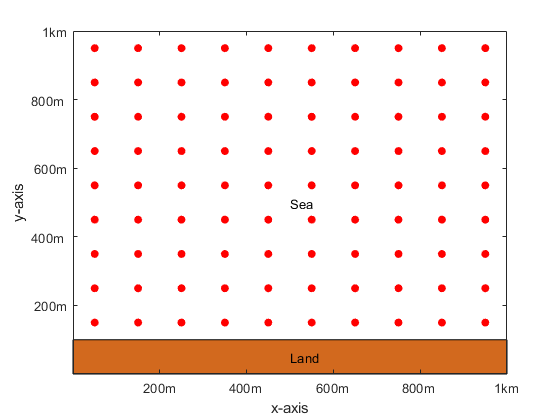

clear all

f = figure;
f.Position = f.Position.*[1 1 1 1];
clf

xl = [0:0.01:1];
yl = 0.1*ones(1,size(xl,2));
ha = area(xl,yl);
xticks([0:0.2:1])
xticklabels({' ','200m','400m ','600m','800m ','1km'})
yticks([0:0.2:1])
yticklabels({' ','200m','400m ','600m','800m ','1km'})
ha.FaceColor = [210/255 105/255 30/255];
xlabel('x-axis') ; ylabel('y-axis')
axis([0 1 0 1])
text(0.5,0.05,'Land')
text(0.5,0.5,'Sea')

m=10;
[g_x,g_y] = meshgrid(1/(2*m):1/(m):1-1/(2*m),1/(2*m):1/(m):1-1/(2*m));
hold on
scatter(g_y(11:end),g_x(11:end),'filled','or');

We have recording of the flow velocity in both the x and y directions at each location of the sensor, i.e., the red dots, once every 30 days, for a total period of 200 days.

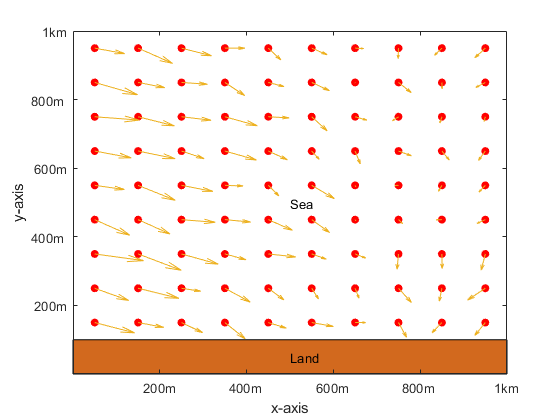

clear all
f = figure;
f.Position = f.Position.*[1 1 1 1];
clf

xl = [0:0.01:1];
yl = 0.1*ones(1,size(xl,2));
ha = area(xl,yl);
xticks([0:0.2:1])
xticklabels({' ','200m','400m ','600m','800m ','1km'})
yticks([0:0.2:1])
yticklabels({' ','200m','400m ','600m','800m ','1km'})
ha.FaceColor = [210/255 105/255 30/255];
xlabel('x-axis') ; ylabel('y-axis')
axis([0 1 0 1])
text(0.5,0.05,'Land')
text(0.5,0.5,'Sea')

m=10;
[g_x,g_y] = meshgrid(1/(2*m):1/(m):1-1/(2*m),1/(2*m):1/(m):1-1/(2*m));
hold on
g2_x = g_x;
g2_x(1:10:end) = [];
g2_y = g_y;
g2_y(1:10:end) = [];
scatter(g2_x,g2_y,'filled','or');

%% Set a random flow for each region
v_y = -0.004*rand(m);                % Generates a grid of 2x2 of random velocities for the x-axis
v_x = -0.004*rand(m)+0.002-0.01*(g_y-0.8);                 % Generates a grid of 2x2 of random velocities for the x-axis

v_x(1:10) =0;
v_y(1:10) =0;

%Plot the flow information
hq = quiver(g_y,g_x,v_x,v_y);

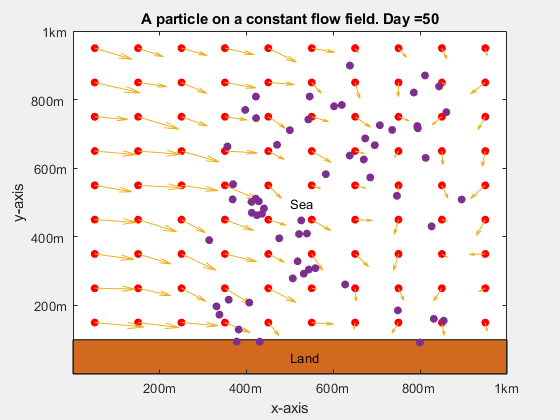

 

T = 200;
n = 60;
epsilon=1;
t = [0:epsilon:T];              % Create the vector of times

%Bounding the space limits, upper and lower limits for the x and y axis
x_max = 1;
x_min = 0;
y_max = 1;
y_min = 0;

%We assign a random initial position to each particle
x_0_x = rand(n,1);
x_0_y = 0.8*rand(n,1)+0.2;

x_x = x_0_x;
x_y = x_0_y;
h= scatter(x_x,x_y,'filled','o');


for i=1:T
     title(strcat('A particle on a constant flow field. Day =',num2str(i)))
     
    xp_x(:,i) = x_x;
    xp_y(:,i) = x_y;
    
    % Now we determine the location of the particle to set up the speed
    % We will check this for the two coordinates independently
    ind_g_x = ceil(m*x_x+1/(2*m));
    ind_g_x(ind_g_x>m) =m;              % Just checking that we dont go out of bounds
    ind_g_x(ind_g_x<1) =1;              % Just checking that we dont go out of bounds
    
    ind_g_y = ceil(m*x_y+1/(2*m));
    ind_g_y(ind_g_y>m) =m;              % Just checking that we dont go out of bounds
    ind_g_y(ind_g_y<1) =1;              % Just checking that we dont go out of bounds
    
    v(:,1) = v_x(sub2ind([m,m],ind_g_x',ind_g_y'))';  % Set the new speed according to the region 
    v(:,2) = v_y(sub2ind([m,m],ind_g_x',ind_g_y'))';  % Set the new speed according to the region
    
    x_x = x_x + epsilon*v(:,1);                          % Compute the next position value
    x_y = x_y + epsilon*v(:,2);                          % Compute the next position value
    
    %Drawing point in new position and changing the time information
    set(h, 'XData', x_x, 'YData', x_y)
     
    if mod(i,30)==0
       
        v_y = -0.004*rand(m);                % Generates a grid of 2x2 of random velocities for the x-axis
        v_x = -0.004*rand(m)+0.002-0.01*(g_y-0.8);
        
        v_x(1:10) =0;
        v_y(1:10) =0;

        set(hq,'UData',v_x, 'VData', v_y);
        
    end
    drawnow;
end